# Sistemas de Visión Artificial

# **Práctica 2. Técnicas Básicas de Procesamiento de Imágenes**

**Autor(es): Isaac Marval y Diego Pena**

**Fecha: **

El objetivo principal de esta práctica es familiarizarse con las **técnicas básicas de procesamiento de imágenes mediante la *****Image Processing Toolbox***** de Matlab**. Para ello se proponen ejercicios sobre operaciones geométricas, ecualización del histograma, diseño e implementación de filtros, eliminación de ruido y filtrado de imágenes en el dominio del espacio. La mayoría de las técnicas de mejora se aplican a imágenes de intensidad (escala de grises). Para mejorar una imagen RGB, trabajaremos, normalmente, con las matrices de las componentes rojo, verde y azul separadamente. Para la realización de los ejercicios se propone inicialmente utilizar las imágenes disponibles en el aula virtual de la asignatura, pero se pueden utilizar otras siempre que se mantengan las características de formato y luminosidad requeridas por el ejercicio (por ejemplo, si deben ser en color, indexadas, oscuras, con bajo contraste, etc...). En cualquier caso, es muy importante verificar el **formato** de cada imagen antes de procesarla: saber si es RGB, indexada, si lo valores son enteros (uint8, etc.), o si son float/double, ya que frecuentemente las funciones solo funcionan con un tipo de datos concreto. Esto es especialmente importante cuando en los ejercicios no se indica qué conversión debe realizarse o cuando se utilizan fotos diferentes a las inicialmente indicadas en el enunciado. Si nuestra imagen no tiene el formato adecuado puede que las funciones den un error (indicándonos el tipo de datos esperado) o proporcionen un resultado inesperado. En cualquiera de los dos casos debemos verificar el tipo de datos esperado por la función y cambiar el formato de la imagen con la función de conversión adecuada.

**La práctica se completará en este mismo fichero .mlx**, añadiendo el nombre del autor/autores del grupo, fecha, e insertando el código y los comentarios pertinentes en cada apartado. Las distintas partes serán secciones independientes (deberá insertar *"section break"* entre ellas), y se visualizarán los resultados conjuntamente con *subplot* cuando sea conveniente. Para evitar problemas al visualizar las imágenes (pueden "perderse" imágenes al superponerse las de los siguientes apartados y/o mostrarse en apartados posteriores), antes de cada "imshow" es necesario incluir un comando "figure", y los distintos apartados deben estar separados en secciones independientes insertando un "section break" entre ellas (en el código se añade escribiendo "%%" y también se puede añadir pinchando en la opción correspondiente del menú).

De cara a facilitar el aprendizaje y el estudio para la preparación de los test de laboratorio, se recomienda la **ampliación** con las explicaciones oportunas, pruebas adicionales (modificando parámetros, utilizando otras imágenes que resalten algún efecto del procesamiento, etc.), descripción de problemas surgidos en la ejecución de la práctica y solución proporcionada, etc. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos -> Entregables -> Práctica 2.

clear all
close all

Implemente el siguiente código, visualice los resultados obtenidos y justifíquelos:

1. Abra y visualice al menos 2 imágenes en color, una de tipo RGB y otra indexada. Para averiguar el formato de cada una puede utilizar previamente *imfinfo * (RGB, indexado, etc.), observando el campo 'Colortype'. Al abrirlas debe utilizar las variables adecuadas (J, X, map, etc...) para que se visualicen correctamente. Utilice figuras diferentes para cada una (evitando, en este caso, el comando *subplot*). 

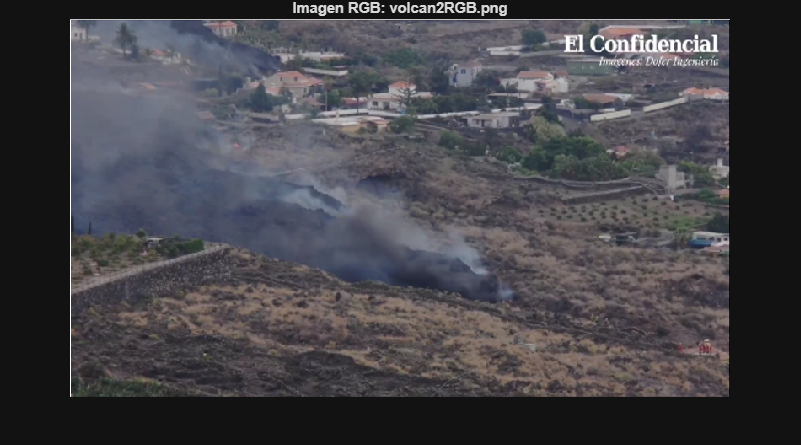


% La función imread carga la imagen. Para un RGB, devuelve una matriz I.
I_RGB = imread('Imagenes/volcan2RGB.png');
% Visualizar en una nueva figura. Usamos 'figure' para que no se superponga
% con otras figuras.
figure, imshow(I_RGB);
title('Imagen RGB: volcan2RGB.png');

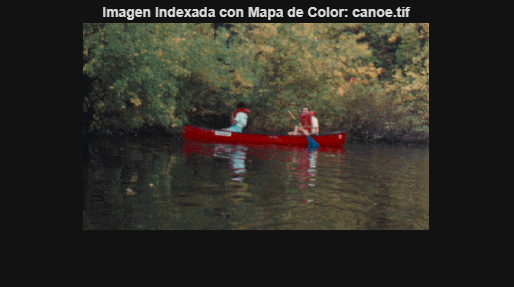



% La función 'load' carga variables desde un archivo .mat. En este caso,
% carga X (matriz de índices) y map (mapa de color)[cite: 68].
[X, map] = imread('Imagenes/canoe.tif'); 

figure, imshow(X, map); % Ahora imshow usa los índices X y el mapa de color M
title('Imagen Indexada con Mapa de Color: canoe.tif');



info_volcan = imfinfo('Imagenes/volcan2RGB.png');
disp(['Tipo de Color de volcan2RGB.png: ', info_volcan.ColorType]);

Tipo de Color de volcan2RGB.png: truecolor


info_canoe = imfinfo('Imagenes/canoe.tif');
disp(['Tipo de Color de canoe: ', info_canoe.ColorType]);

Tipo de Color de canoe: indexed


2. Convierta la imagen indexada en escala de grises (imagen Igris) y sobre ella:

    2.1 Modifique el brillo y el contraste. Visualice las imágenes (original y resultantes) y sus histogramas de forma conjunta utilizando el comando *subplot*. Explique cuándo la modificación es de brillo y cuándo es de contraste, justificando los valores de los intervalos utilizados en cada caso.

    2.2 Binarice la imagen Igris con la función *im2bw* y visualice el resultado y su histograma.

    2.3 Obtenga el negativo de la imagen Igris y visualice el resultado y su histograma.

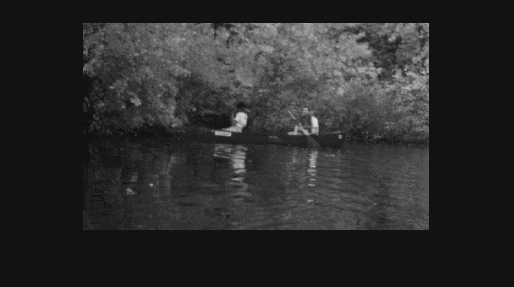

% 2. Conversión a Escala de Grises (Igris)
% ind2gray convierte la imagen indexada (X, map) a intensidad (double, 0 a 1).
I_gris = ind2gray(X, map);
figure, imshow(I_gris);

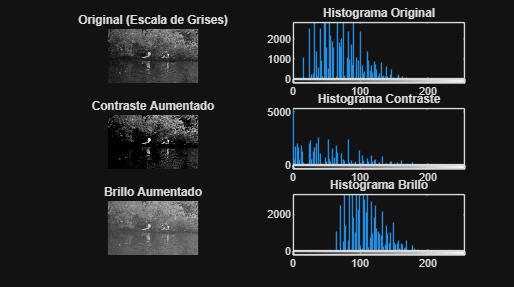

I_contraste = imadjust(I_gris, [0.2 0.8], [0 1]);
I_brillo = imadjust(I_gris, [0 1], [0.2 1]); 
% Visualización y Histogramas
subplot(3, 2, 1), imshow(I_gris), title('Original (Escala de Grises)');
subplot(3, 2, 2), imhist(I_gris, 128), title('Histograma Original');

subplot(3, 2, 3), imshow(I_contraste), title('Contraste Aumentado');
subplot(3, 2, 4), imhist(I_contraste, 128), title('Histograma Contraste');

subplot(3, 2, 5), imshow(I_brillo), title('Brillo Aumentado');
subplot(3, 2, 6), imhist(I_brillo, 128), title('Histograma Brillo');

## 2.2 Binarización

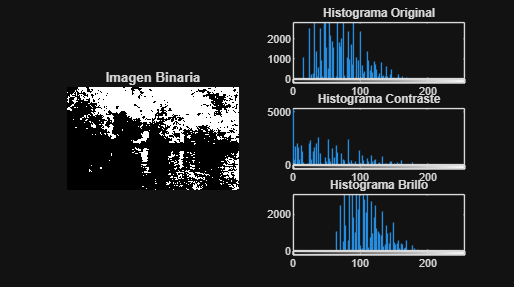


% Usamos im2gray si la imagen de entrada es a color. Como ya tenemos I_gris,
% usamos imbinarize (la versión moderna y más flexible de im2bw).
% Si la imagen I_gris es double, imbinarize funciona directamente.
% Por defecto, usa el método de Otsu para encontrar el umbral óptimo.
I_binaria = imbinarize(I_gris); 

subplot(1, 2, 1), imshow(I_binaria), title('Imagen Binaria');

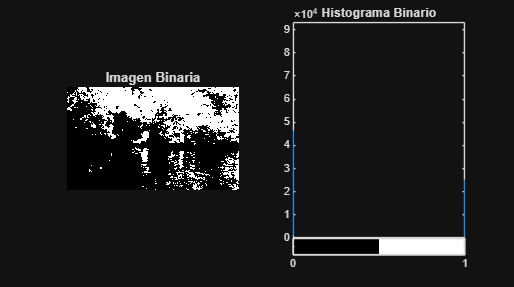

% Para una imagen binaria, el histograma solo mostrará barras en 0 y 1.
subplot(1, 2, 2), imhist(I_binaria), title('Histograma Binario');

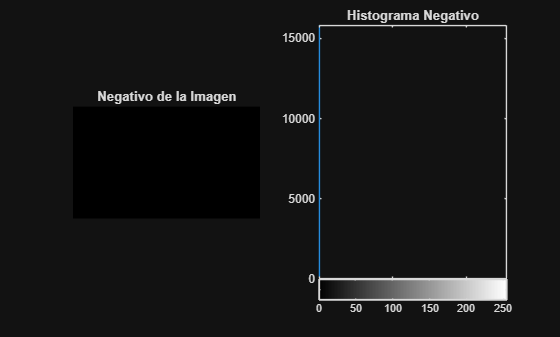


%% 2.3 Negativo de la Imagen
figure,

% Cálculo del negativo: 1 - I_gris (porque el rango es de 0 a 1)
I_negativo = 1 - I_gris;

subplot(1, 2, 1), imshow(I_negativo), title('Negativo de la Imagen');
% El histograma del negativo es un reflejo invertido del histograma original.
subplot(1, 2, 2), imhist(I_negativo, 128), title('Histograma Negativo');

3. Sobre la imagen "avion1.jpg":

    3.1 Realice una corrección gamma. Pruebe con distintos valores de gamma y analice el efecto de cada uno sobre la imagen de salida.

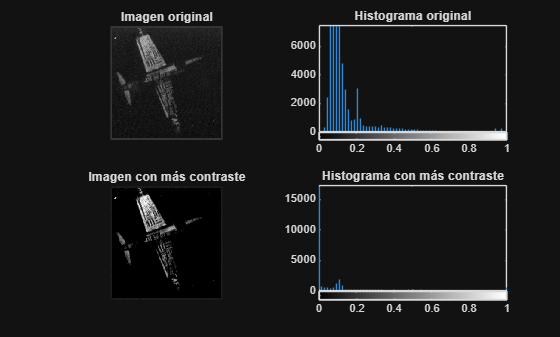

%% 3.1) Ajuste de intensidad con imadjust - Imagen avion1.jpg
I_avion = imread('Imagenes/avion1.jpg');      % Lee la imagen
I_avion = rgb2gray(I_avion);               % Convierte a escala de grises
I_avion = im2double(I_avion);              % Convierte a tipo double en [0,1]

% --- AUMENTAR CONTRASTE ---
J = imadjust(I_avion, [0.15 0.7], [0 1]);  % estira el rango útil

figure;
subplot(2,2,1), imshow(I_avion); title('Imagen original');
subplot(2,2,2), imhist(I_avion,64); title('Histograma original');
subplot(2,2,3), imshow(J); title('Imagen con más contraste');
subplot(2,2,4), imhist(J,64); title('Histograma con más contraste');




% El valor de gamma permite controlar el contraste en diferentes rangos de intensidad.
% Un gamma < 1 aumenta la separación entre los valores oscuros (aclarándolos)
% mientras que un gamma > 1 aumenta la separación entre los valores brillantes (oscureciéndolos).

    3.2 Ecualice su histograma uniformemente con 256, 64 y 8 bins (consulte la ayuda de histeq). Visualice las imágenes (original y resultantes) y sus histogramas y comente las diferencias.

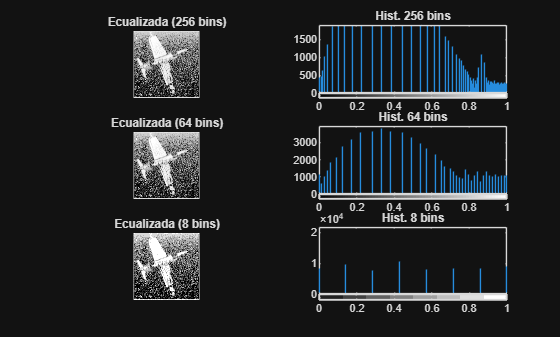


%% 3.2 Ecualización de Histograma
figure,

% Ecualización con diferentes niveles (bins)
I_eq256 = histeq(I_avion, 256); % Máximo de niveles (histograma más fino)
I_eq64 = histeq(I_avion, 64);
I_eq8 = histeq(I_avion, 8);   % Menos niveles (histograma más plano, menos detalle) 

% Visualización de las imágenes ecualizadas
subplot(3, 2, 1), imshow(I_eq256), title('Ecualizada (256 bins)');
subplot(3, 2, 2), imhist(I_eq256, 256), title('Hist. 256 bins');

subplot(3, 2, 3), imshow(I_eq64), title('Ecualizada (64 bins)');
subplot(3, 2, 4), imhist(I_eq64, 64), title('Hist. 64 bins');

subplot(3, 2, 5), imshow(I_eq8), title('Ecualizada (8 bins)');
subplot(3, 2, 6), imhist(I_eq8, 8), title('Hist. 8 bins');

4. Sobre la imagen "matricula.jpg":

    4.1 Averigüe sus dimensiones (filas x columnas). Modifique su tamaño para que mida la mitad de ancho y de alto. Visualice ambas figuras. Para poder ver el cambio de tamaño debe utilizar la instrucción *truesize *después de *imshow *para que las imágenes no ajusten su tamaño al de la ventana.

figure,

I_matricula = imread('Imagenes/matricula.jpg');
% 4.1. Modificación de Tamaño y truesize
[filas, columnas] = size(I_matricula); % Averiguar dimensiones
disp(['Dimensiones Originales: ', num2str(filas), 'x', num2str(columnas)]);

Dimensiones Originales: 187x1500


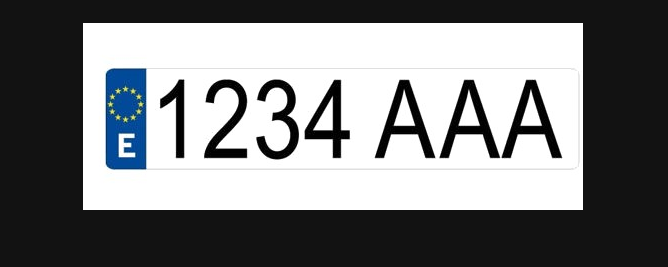

figure, imshow(I_matricula);

nuevas_filas = (filas / 2);
nuevas_columnas = (columnas / 2);
I_reducida = imresize(I_matricula, [nuevas_filas, nuevas_columnas]);

subplot(1, 2, 1), imshow(I_matricula), title('Original'); 

% 4.1. Modificación de Tamaño y truesize
[filas, columnas] = size(I_matricula); % Averiguar dimensiones
disp(['Dimensiones Originales: ', num2str(filas), 'x', num2str(columnas)]);

Dimensiones Originales: 187x1500



% Reducir a la mitad de ancho y alto
nuevas_filas = round(filas / 2);
nuevas_columnas = round(columnas / 2);
disp(['Nuevas Dimensiones: ', num2str(nuevas_filas), 'x', num2str(nuevas_columnas)]);

Nuevas Dimensiones: 94x750


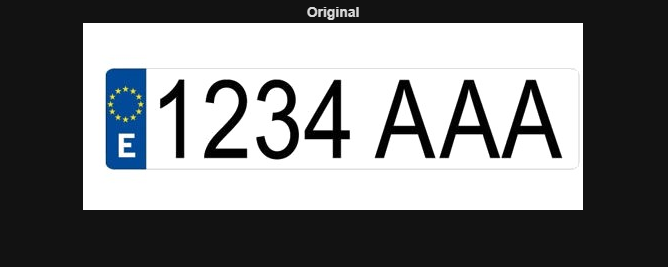


% imresize cambia el tamaño
I_reducida = imresize(I_matricula, [nuevas_filas, nuevas_columnas]);

subplot(1, 2, 1), imshow(I_matricula), title('Original'); 
truesize; % Muestra el tamaño real de la imagen en la pantalla 

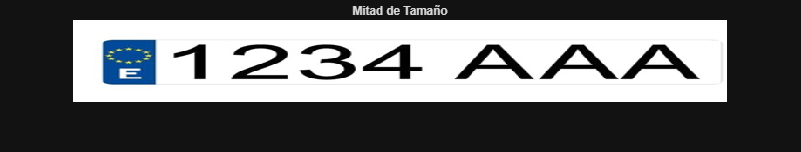


subplot(1, 2, 2), imshow(I_reducida), title('Mitad de Tamaño'); 
truesize; % Muestra el tamaño real (se verá la imagen más pequeña)

    4.2 Rótela un ángulo de 65,3º (por ejemplo), utilizando los métodos de interpolación *nearest* y *bicubic* (parámetros de la función *imrotate*). Aumente las imágenes lo suficiente para ver las diferencias entre ambos resultados y explíquelas.

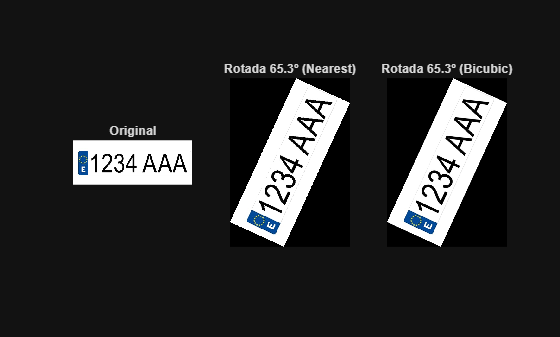

%% 4.2 Rotación con Diferentes Interpolaciones
figure,

angulo = 65.3;

% Rotación con Nearest (Vecino más Cercano) 
% Es el método más rápido, pero con más artefactos (escalones).
I_nearest = imrotate(I_matricula, angulo, 'nearest');

% Rotación con Bicubic (Bicúbica) 
% Es el método más lento, pero ofrece la mejor calidad (más suave).
I_bicubic = imrotate(I_matricula, angulo, 'bicubic');

subplot(1, 3, 1), imshow(I_matricula), title('Original');
subplot(1, 3, 2), imshow(I_nearest), title(['Rotada ', num2str(angulo), 'º (Nearest)']);
subplot(1, 3, 3), imshow(I_bicubic), title(['Rotada ', num2str(angulo), 'º (Bicubic)']);

5. A partir de la imagen "cell.tif":

    5.1 Obtenga y muestre una versión con ruido de distribución uniforme ‘speckle’. Elimínelo con un filtrado de Wiener y con un filtro paso bajo. Muestre las imágenes original, con ruido y filtradas y compárelas.

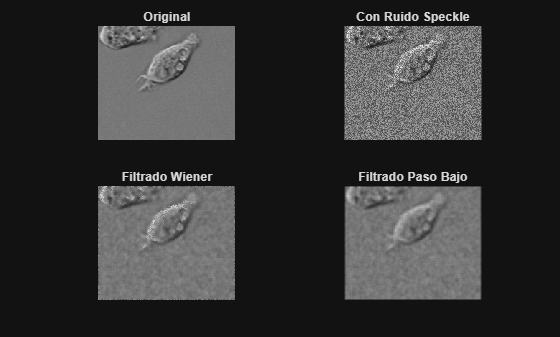

%% 5. A partir de la imagen "cell.tif"

I_cell = imread('imagenes/cell.tif');
I_cell = im2double(I_cell); % Convertir a double para operaciones de ruido/filtrado

% 5.1. Ruido Speckle y Filtrado Wiener vs. Paso Bajo
figure,
% Ruido 'speckle' (multiplicativo, de distribución uniforme)
I_speckle = imnoise(I_cell, 'speckle');

% Filtro de Wiener
I_wiener_speckle = wiener2(I_speckle, [5 5]); % Ventana 5x5

% Filtro Paso Bajo (Promedio) - Filtro de media de 5x5
filtro_promedio = fspecial('average', [5 5]); % Crea un filtro de promedio
I_pasobajo_speckle = imfilter(I_speckle, filtro_promedio);

subplot(2, 2, 1), imshow(I_cell), title('Original');
subplot(2, 2, 2), imshow(I_speckle), title('Con Ruido Speckle');
subplot(2, 2, 3), imshow(I_wiener_speckle), title('Filtrado Wiener');
subplot(2, 2, 4), imshow(I_pasobajo_speckle), title('Filtrado Paso Bajo');

    5.2 Obtenga una versión con ruido de tipo ‘sal y pimienta’ de densidad de ruido 5%. Fíltrela utilizando un filtro de mediana y con un filtro paso bajo. Muestre las imágenes original, con ruido y filtradas y compare los resultados: ¿qué tipo de filtrado es más adecuado para este tipo de ruido? Justifique sus conclusiones.

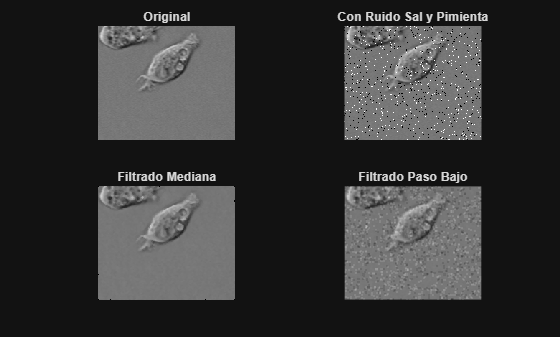

% 5.2. Ruido Sal y Pimienta y Filtrado Mediana vs. Paso Bajo
figure,
% Ruido 'salt & pepper' (impulsivo, de densidad 0.05)
I_saltpepper = imnoise(I_cell, 'salt & pepper', 0.05);

% Filtro de Mediana
I_mediana_sp = medfilt2(I_saltpepper, [3 3]); % Ventana 3x3

% Filtro Paso Bajo (Promedio) - Filtro de media de 3x3
filtro_promedio_sp = fspecial('average', [3 3]);
I_pasobajo_sp = imfilter(I_saltpepper, filtro_promedio_sp);

subplot(2, 2, 1), imshow(I_cell), title('Original');
subplot(2, 2, 2), imshow(I_saltpepper), title('Con Ruido Sal y Pimienta');
subplot(2, 2, 3), imshow(I_mediana_sp), title('Filtrado Mediana');
subplot(2, 2, 4), imshow(I_pasobajo_sp), title('Filtrado Paso Bajo');

% el filtro de mediana es mejor

5.3  Obtenga y muestre una versión con ruido de tipo gaussiano de media cero y varianza 0.01, "Ig", fíltrela utilizando la media del entorno de vecindad, primero con un entorno de vecindad de 3x3 y luego con uno de 5x5, comparando los resultados obtenidos. Justifique sus conclusiones.

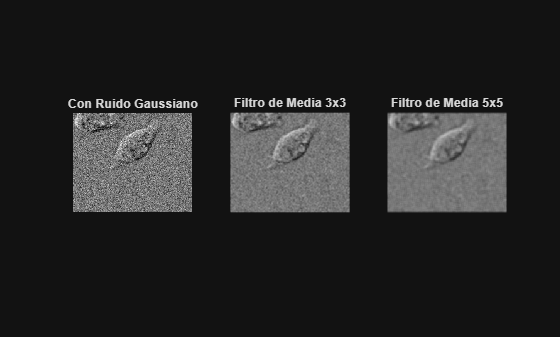

% 5.3. Ruido Gaussiano y Filtrado de Media con diferentes vecindades
figure,
% Ruido 'gaussian' (aditivo)
I_gaussian = imnoise(I_cell, 'gaussian', 0, 0.01); % Media 0, Varianza 0.01

% Filtro de Media 3x3
filtro_avg3 = fspecial('average', [3 3]);
I_avg3 = imfilter(I_gaussian, filtro_avg3);

% Filtro de Media 5x5
filtro_avg5 = fspecial('average', [5 5]);
I_avg5 = imfilter(I_gaussian, filtro_avg5);

subplot(1, 3, 1), imshow(I_gaussian), title('Con Ruido Gaussiano');
subplot(1, 3, 2), imshow(I_avg3), title('Filtro de Media 3x3');
subplot(1, 3, 3), imshow(I_avg5), title('Filtro de Media 5x5');

% El promedio reduce la variación (el ruido) a costa de un ligero desenfoque de la imagen.
% El filtro de 5x5 es más efectivo en la reducción de ruido que el de 3x3, pero causa un mayor desenfoque

    5.4 Con un bucle *for, *obtenga 32 imágenes diferentes aplicando ruido gaussiano de media cero y varianza 0.05 a "cell.tif" y guárdelas utilizando la función *imwrite* en ficheros con sus respectivos nombres (ruidosa1.bmp, …, ruidosa32.bmp). Puede generar los nombres de los ficheros dentro del bucle *for* utilizando, por ejemplo: "ruidosa" + i + ".bmp". Realice pruebas de filtrado de ruido usando la técnica de promediado de imágenes, utilizando en primer lugar 4 imágenes ruidosas, luego 8, después 16 y, finalmente, las 32. Compare visualmente los resultados (mostrándolos en la misma imagen con *subplot*) y coméntelos.

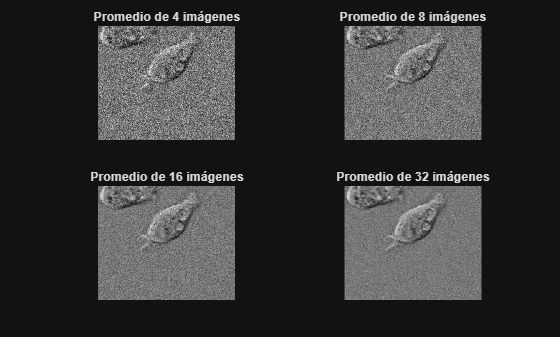

% 5.4. Promediado de Imágenes para Reducción de Ruido Gaussiano
figure,
varianza = 0.05;
num_imagenes = 32;
sum_img = zeros(size(I_cell));
filtro_imgs = cell(1, 4); % Para guardar las imágenes filtradas

% Bucle para generar y guardar las 32 imágenes ruidosas
for i = 1:num_imagenes
    I_ruidosa = imnoise(I_cell, 'gaussian', 0, varianza);
    
    % Acumular para el promediado (suma de todas las imágenes)
    sum_img = sum_img + I_ruidosa;
    
    % Generar nombre del archivo
    nombre_archivo = ['ruidosa', num2str(i), '.bmp'];
    imwrite(I_ruidosa, nombre_archivo); % Guardar imagen
    
    % Obtener la imagen promedio para 4, 8, 16 y 32 imágenes
    if i == 4
        filtro_imgs{1} = sum_img / 4;
    elseif i == 8
        filtro_imgs{2} = sum_img / 8;
    elseif i == 16
        filtro_imgs{3} = sum_img / 16;
    elseif i == 32
        filtro_imgs{4} = sum_img / 32;
    end
end

% Visualizar el promediado
subplot(2, 2, 1), imshow(filtro_imgs{1}), title('Promedio de 4 imágenes');
subplot(2, 2, 2), imshow(filtro_imgs{2}), title('Promedio de 8 imágenes');
subplot(2, 2, 3), imshow(filtro_imgs{3}), title('Promedio de 16 imágenes');
subplot(2, 2, 4), imshow(filtro_imgs{4}), title('Promedio de 32 imágenes');

% como promediamos imagenes, cuantas mas utilicemos, mas se reduce el ruido